# Preview Webcam Live Video Stream with Custom Window

Apply custom settings to the preview window that displays live video from your webcam. This feature is not supported in MATLAB® Online™.

Find the name of your camera using the `webcamlist` function to ensure that MATLAB is discovering your camera.

webcamlist

Use the `webcam` function with the name of the camera as the input argument to create the object and connect to the camera with that name. Use `cam` as the name of the object.

cam = webcam('Logitech');

Create a figure object, and specify its properties. In this example, the figure number is not displayed in the title bar and menus are not displayed at the top of the figure window. Set the `Name` property to '`My Camera'`. You can change these properties to further customize your figure window.

fig = figure('NumberTitle','off','MenuBar','none');
fig.Name = 'My Camera';

To display live video steam on your webcam in the figure, identify these additional properties. Create an `Axes` object from your figure. Call this object `ax`. Define the dimensions of the webcam images by capturing a single image from the webcam, and call it f`rame`. Create an `Image` object using these two variables, and call this object `im`. Set the axis limits for your figure window with `ax`, and specify the style as `'image'`.

ax = axes(fig); 
frame = snapshot(cam); 
im = image(ax,zeros(size(frame),'uint8')); 
axis(ax,'image');

Preview the live video stream from the webcam in the custom figure window you generated with the properties you set.

preview(cam,im)

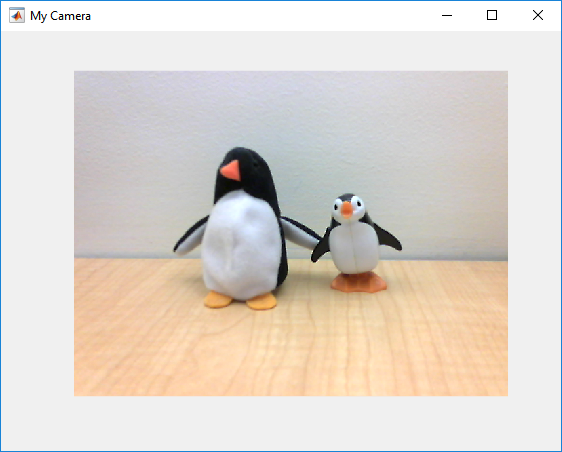

*Copyright 2020 The MathWorks, Inc*